# AI Train and Test Pipeline

This live script has been designed for the purpose of MECH5030 Group Project and is used to take lots of datasets then filter and featurise them. Once this has been done the data is split into train and test sets and used the compare the performance of different AI/ML models.

- *Ingest all datasets into a single Matlab variables*

- *Pre-process the data (Cleaning and Filtering)*

- *Featurise the data*

- *Sort data in train_x, train_y and test_x, test_y*

- *Evaluate the performance of different AI modelling approaches*

## Introduction

### 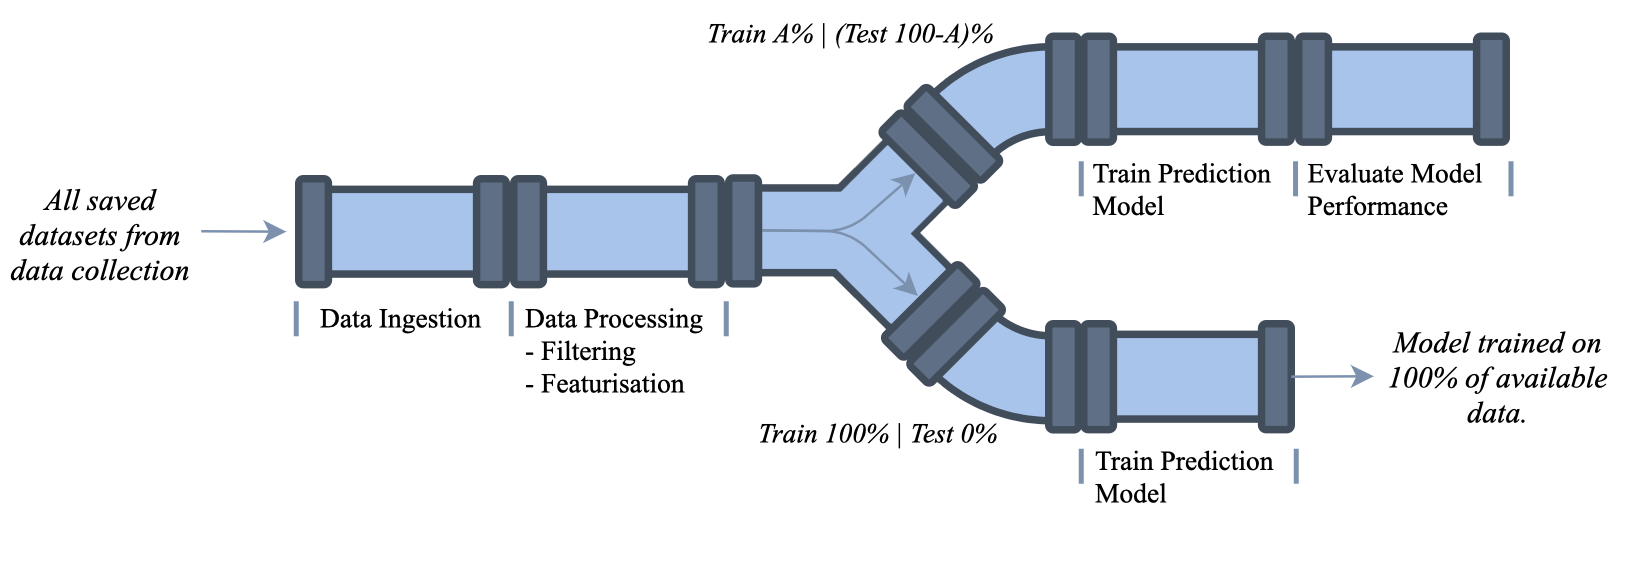

*AI Pipeline Diagram*

## Live Script Setup

Adds the folder path to the script so that custom pre-processing functions can be accessed from the script without having to manually add the path

addpath('Data Processing Functions')

Removes all variables from the workspace.

clear;  %% Clears all variables from the workspace

The line below line makes sure the program from this point on will be repeatable.

rng=0;  %% Ensures the program is repeatable

## Data Ingestion

    *The purpose of this stage is to aquire all the datasets and store them inside 1 Matlab variable for later use.*

    The below is an array of the different motions that have been collected and stored. 

***    IMPORTANT****: These should match the folder names that the data recordings are stored in*

list_of_motions = ["Motion 1","Motion 2","Motion 3","Motion 4"];

    Once the list of different motions is entered the entire dataset can be loaded using the below function.

    The function looks within the folder '*Matlab App Data Tables*' for two folders: 'Right Arm' and 'Left Arm'. If these folders exist then the function gathers all the data within them and stores it as a 'table of tables'. The table will hold all recordings ever found in these folders and does not filter out any specific filenames so ensure the files in the folder are correct.

data_folder_name = "Matlab App Data Tables";
addpath(data_folder_name)
trials_data = LoadTrialData(data_folder_name, list_of_motions);
%disp(trials_data)  %% Displays the data within the table

This table of tables makes it simple to access the data you want to use. Below is an example of how data would be extracted from this:

*Example dataset that was collected for the left arm, motion 1:*

% head(TABLE, X) is used to display the top X rows of TABLE helps Matlab
% compute if we display less data when it is not needed
head(trials_data.("Left Arm").("Motion 1"){:,:}{1,1}{:,:}, 3)

ans = 3×31 table
    timestamp     accelX_1    accelY_1    accelZ_1    gyroX_1    gyroY_1    gyroZ_1    magX_1    magY_1    magZ_1     accelX_2    accelY_2    accelZ_2    gyroX_2    gyroY_2    gyroZ_2    magX_2    magY_2    magZ_2    accelX_3    accelY_3    accelZ_3    gyroX_3    gyroY_3    gyroZ_3    magX_3     magY_3    magZ_3    movement_type    movement_completeness    movement_smoothness
    __________    ________    _____

clear data_folder_name list_of_motions

## Data Pre-Processing

### Formatting Timestamps

Currently the timestamps in the table aren't very useful as they show the number of milliseconds since the Arduino was turned on. A simple function is used to convert all of the timestamps to a useful time since recording started. Below shows the first 4 columns of an example dataset where 'time' has been inserted in the 2nd column.

trials_data_with_time = AddTimeToTrialData(trials_data);
head(trials_data_with_time.("Left Arm").("Motion 1"){:,:}{1,1}{:,:}(:,1:4), 3)

ans = 3×4 table
    timestamp       time      accelX_1    accelY_1
    __________    ________    ________    ________

    7.5229e+05       0 sec     9.542       0.245  
    7.5234e+05    0.05 sec     9.347       0.311  
    7.5239e+05     0.1 sec     9.492       0.346  


### Clean Missing/Lagged Data

Although with bluetooth it is highly unlikely that any NaN data will be recieved it is likely that data may be buffered and reading it into a table might cause it to lag.

Do we need to do this???? Test datasets to see if there is any lag and if so how much?

### Data Filtering

The recorded IMU data is very noisy and requires filtering/smoothing to make it more useable.

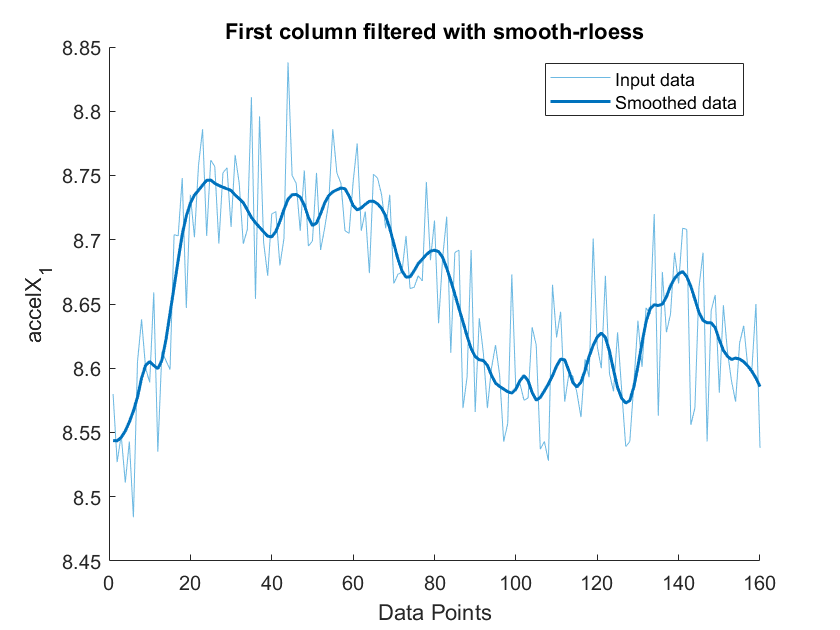

filtered_trials_data = FilterTrialData(trials_data_with_time,'smooth-rloess',800,true);

### Data Featurisation

*This section of the pipeline allows the filtered IMU data to be featurised by performing various statistical calculations on groups of the data.*

    The desired statistical features that want to be added have to provided as well as the amount of time that the data is to be grouped by, the delta t. The chosen statistical calculations are then performed on the different groups of acceleration, magnetometer and gyroscopic data in all directions. The resulting table is all the featurised data horizontally concatenated for each 'delta t' group.

featurised_data = FeatureDataTable(['max','min','std','mean','var','jerk','rms'],filtered_trials_data,250);
head(featurised_data.("Left Arm").("Motion 1"){:,:}{1,1}{:,:}, 3)

ans = 3×138 table
    accelX_1_max    accelX_1_min    accelX_1_mean    accelX_1_std    accelX_1_var    accelY_1_max    accelY_1_min    accelY_1_mean    accelY_1_std    accelY_1_var    accelZ_1_max    accelZ_1_min    accelZ_1_mean    accelZ_1_std    accelZ_1_var    gyroX_1_max    gyroX_1_min    gyroX_1_mean    gyroX_1_std    gyroX_1_var    gyroY_1_max    gyroY_1_min    gyroY_1_mean    gyroY_1_std    gyroY_1_var    gyroZ_1_max    gyroZ_1_min    gyroZ_1_mean    gyroZ_1_std    gyroZ_1_var 


%clear filtered_trials_data trials_data_with_time trials_data 
save('featurised_data.mat','featurised_data')

## Data Splitting into Train and Test

*In this section the now prepared data is split into a training and a testing dataset. The first step of this section however is to vertically concatenate all the datasets ontop of each other to make a very long table. For our purposes two tables are created; one with all the data of the left arm and one with all the data of the right arm.*

%Vertically concatting all trials into one long table to be used by the
%AI/ML model
[left_arm_data, right_arm_data] = VerticalConcatByArm(featurised_data);

save('left_arm_data.mat','left_arm_data')
disp('Number of data points = ' + string(height(left_arm_data)) )

Number of data points = 3496


The below slider allows for the percentage of data split between train sets and test sets to be modified.

%% Data splitting slider for train / test 
train_data_percent = 70;

Using the above percentage the number of data points are split out as following:

cv = cvpartition(size(left_arm_data,1),"HoldOut",(100-train_data_percent)/100);
idx = cv.test;

dataTrain = removevars(left_arm_data(~idx,:), {'movement_completeness','movement_type'});
dataTest  = removevars(left_arm_data(idx,:), {'movement_completeness','movement_type'});

clear cv idx

disp('Number of train data points = ' + string(height(dataTrain)) )

Number of train data points = 2448


disp('Number of test points = ' + string(height(dataTest)) )

Number of test points = 1048


## Model Training

Desired Output -> A value in the range of 0.2 to 1.0

addpath('Model Evaluation Functions')

### Regression Models

#### Decision Tree

[Matlab Decision Trees](https://uk.mathworks.com/help/stats/decision-trees.html)

This section uses decision tree algoritm to create a machine learning model.

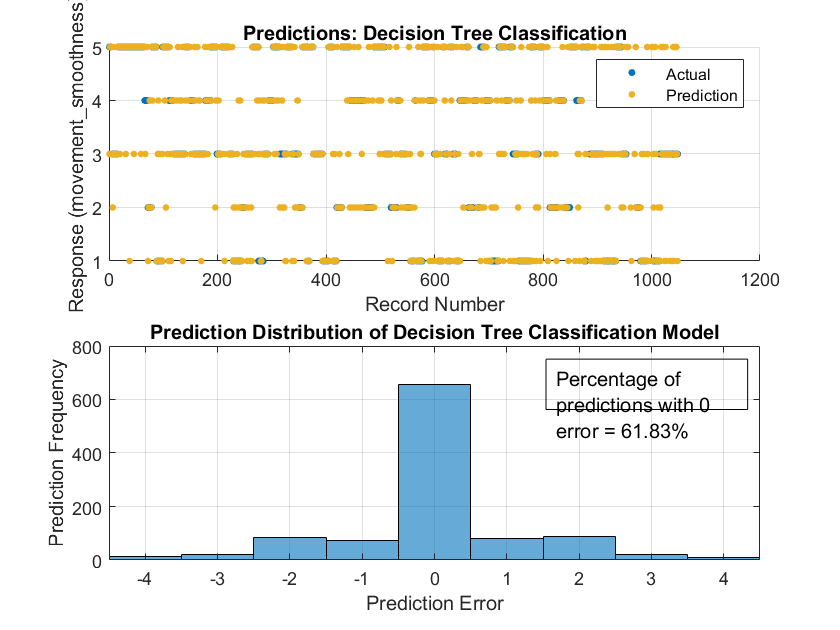

optimize_hyperpara = false;
if ~optimize_hyperpara
    rTreeMdl = fitctree(dataTrain,'movement_smoothness');%"MinLeafSize",8,"MaxNumSplits",1000,'MaxNumCategories',5);
else
    rTreeMdl = fitctree(dataTrain,'movement_smoothness',...
        'OptimizeHyperparameters',{'MaxNumSplits','MinLeafSize','NumVariablesToSample'})
end
[pred_table,pred_plot] = GetPredictionsInfo(rTreeMdl,dataTest,'movement_smoothness','Decision Tree','Classification');

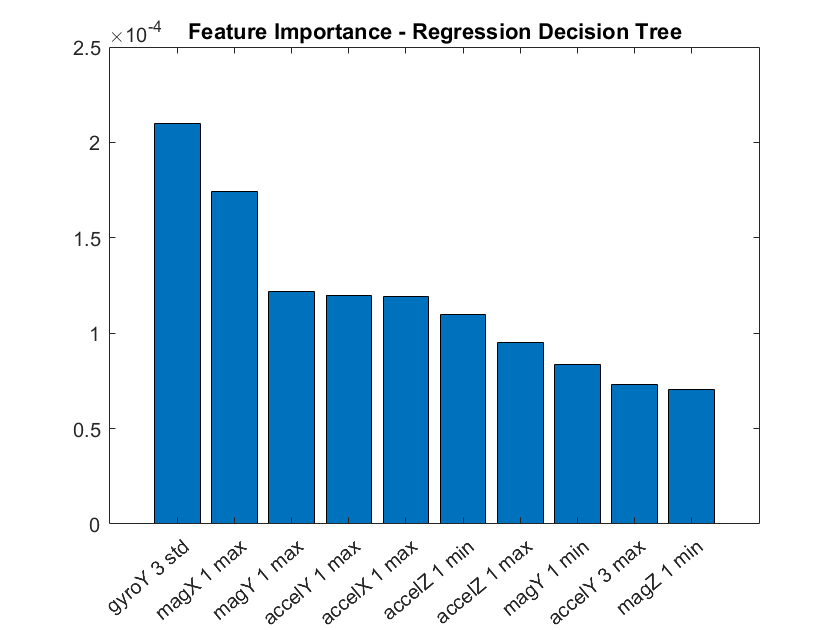

% saveas(pred_plot,'Decision Tree Prediction Plot','jpeg');
GetImportanceInfo(rTreeMdl,10,'Regression Decision Tree');

[conf_matr, tree_metrics] = GetClassificationEvaluation(pred_table.Actual,pred_table.Prediction,"Decision Tree");
tree_metrics.precision

ans =     0.5966
    0.5342
    0.5750
    0.6203
    0.7324


mean(tree_metrics.precision)

ans = 0.6117

mean(tree_metrics.recall)

ans = 0.6245

mean(tree_metrics.f1_score)

ans = 0.6161

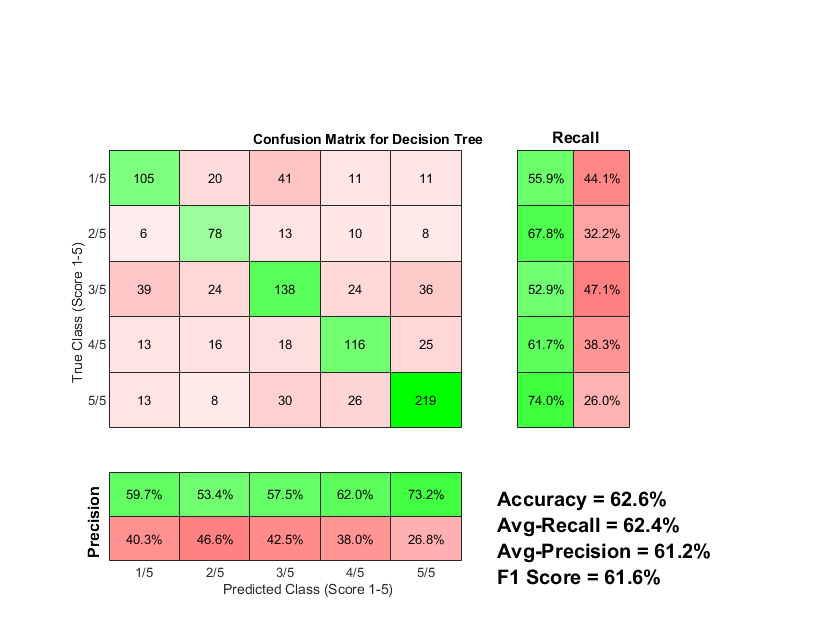


 saveas(conf_matr,'Decision Tree Confusion Matrix','jpeg');

#### Ensemble

[Matlab Ensemble Algorithms](https://uk.mathworks.com/help/stats/ensemble-algorithms.html)

This section uses an ensemble algoritm to create a machine learning model.

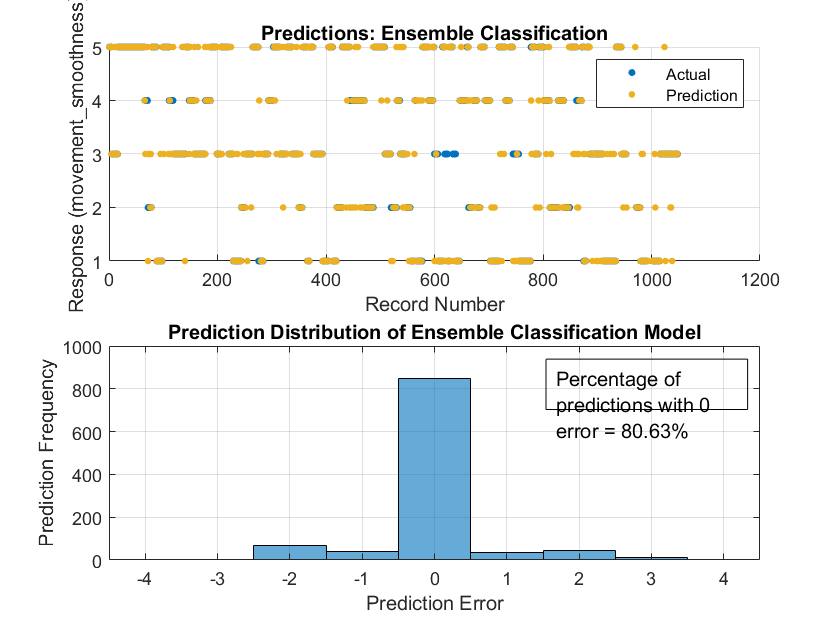

optimize_hyperpara = false;
if ~optimize_hyperpara
    rEnsembleMdl = fitcensemble(dataTrain,'movement_smoothness',...
         "Method","Bag","NumLearningCycles",100);
else
    rEnsembleMdl = fitrensemble(dataTrain,'movement_smoothness',...
        'OptimizeHyperparameters',{'MaxNumSplits','MinLeafSize','NumLearningCycles','Method'})
end
[pred_table,pred_plot] = GetPredictionsInfo(rEnsembleMdl,dataTest,'movement_smoothness','Ensemble',"Classification");

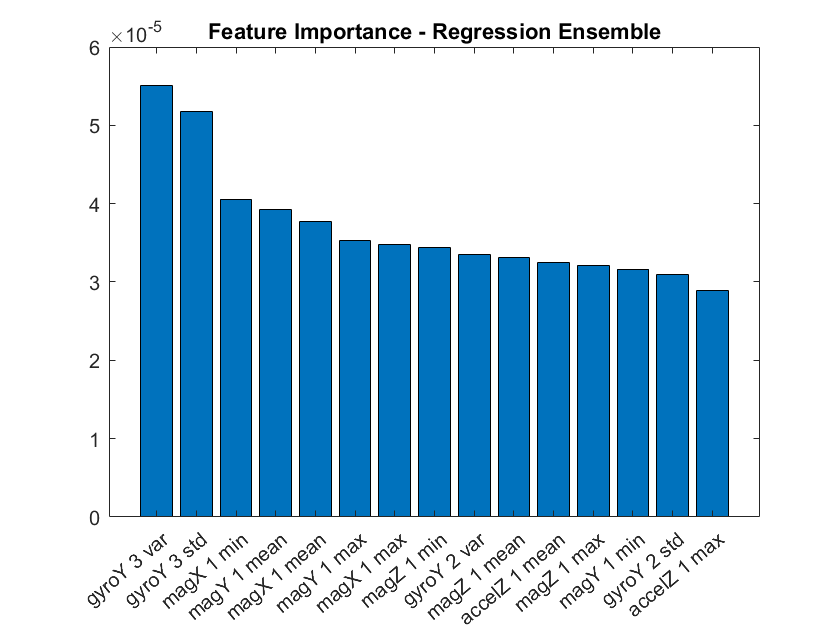

% saveas(pred_plot,'Ensemble Prediction Plot','jpeg');
GetImportanceInfo(rEnsembleMdl,15,'Regression Ensemble');

[conf_matr, ensemble_metrics] = GetClassificationEvaluation(pred_table.Actual,pred_table.Prediction,"Ensemble");
mean(ensemble_metrics.precision)

ans = 0.8003

mean(ensemble_metrics.recall)

ans = 0.8018

mean(ensemble_metrics.f1_score)

ans = 0.7998

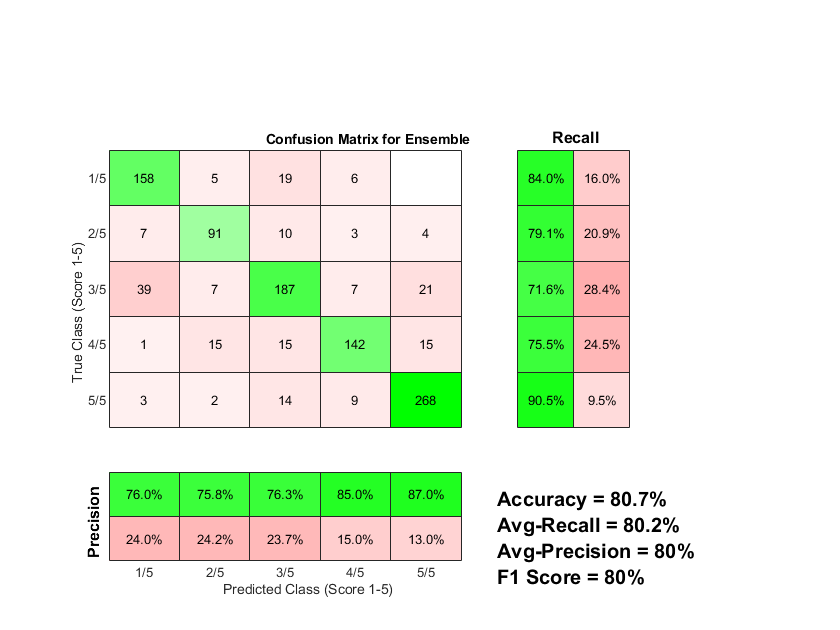

 saveas(conf_matr,'Ensemble Confusion Matrix','jpeg');

#### Support Vector Machine

This section uses a support vector machine algoritm to create a machine learning model

% optimize_hyperpara = false;
% if ~optimize_hyperpara
%     rSvmMdl = fitcecoc(dataTrain,'movement_smoothness');%,"KernelFunction","rbf");
% else
%     rSvmMdl = fitrsvm(dataTrain,'movement_smoothness',...
%         'OptimizeHyperparameters',{'KernelFunction'})
% end
% % [pred_table,pred_plot] = GetPredictionsInfo(rSvmMdl,dataTest,'movement_smoothness','SVM',"Classification");
% % saveas(pred_plot,'SVM Prediction Plot','jpeg');
% %GetImportanceInfo(rSvmMdl,10,'Classification SVM'); %Cant be done for SVM

% [conf_matr, svm_metrics] = GetClassificationEvaluation(pred_table.Actual,pred_table.Prediction,"SVM");
% mean(svm_metrics.precision)
% mean(svm_metrics.recall)
% mean(svm_metrics.f1_score)
% saveas(conf_matr,'SVM Confusion Matrix','jpeg');

#### Gaussian Process

This section uses a gaussian process algoritm to create a machine learning model.

% optimize_hyperpara = false;
% if ~optimize_hyperpara
%     rGpMdl = fitrgp(dataTrain,'movement_smoothness',"KernelFunction","rationalquadratic");
% else
%     rGpMdl = fitrgp(dataTrain,'movement_smoothness',...
%         'OptimizeHyperparameters',{'MaxNumSplits','MinLeafSize','NumLearningCycles','Method'})
% end
% 
% %GetPredictionsInfo(rGpMdl,dataTest,'movement_smoothness','Regression Gaussian Process');

#### Neural Network